clear; clc; close all;

%% user input

% plane loudness
fprintf('Sound Power Level (L_W)\n');

Sound Power Level (L_W)


fprintf(' Small turboprop ~135 dB\n');

 Small turboprop ~135 dB


fprintf(' Narrow-body jet ~155 dB\n');

 Narrow-body jet ~155 dB


fprintf(' Heavy widebody ~165 dB\n');

 Heavy widebody ~165 dB



L_W = input(' Enter L_W [dB] (e.g. 155): ');
while ~isnumeric(L_W) || ~isscalar(L_W) || L_W < 100 || L_W > 200
    fprintf(' Invalid. Enter a value between 100 and 200.\n');
    L_W = input(' Enter L_W [dB]: ');
end

% aircraft altitude
fprintf('\nAltitude\n');


Altitude


fprintf(' Landing approach ~300 m\n');

 Landing approach ~300 m


fprintf(' Low overflight ~600 m\n');

 Low overflight ~600 m


fprintf(' High overflight ~3000 m\n');

 High overflight ~3000 m



h = input(' Enter altitude [m] (e.g. 500): ');
while ~isnumeric(h) || ~isscalar(h) || h <= 0 || h > 15000
    fprintf(' Invalid. Enter a positive value up to 15000 m.\n');
    h = input(' Enter altitude [m]: ');
end

% aircraft speed
fprintf('\nGround Speed\n');


Ground Speed


fprintf(' Final approach ~70 m/s (~250 km/h)\n');

 Final approach ~70 m/s (~250 km/h)


fprintf(' Departure ~100 m/s (~360 km/h)\n');

 Departure ~100 m/s (~360 km/h)


fprintf(' Cruise overflight ~250 m/s\n');

 Cruise overflight ~250 m/s



v = input(' Enter speed [m/s] (e.g. 100): ');
while ~isnumeric(v) || ~isscalar(v) || v <= 0 || v > 400
    fprintf(' Invalid. Enter a value between 0 and 400 m/s.\n');
    v = input(' Enter speed [m/s]: ');
end

% atmospheric absorption
fprintf('\nAtmosperic Absorption (alpha)\n');


Atmosperic Absorption (alpha)


fprintf(' Typical dry air at 1 kHz ~0.002 dB/m\n');

 Typical dry air at 1 kHz ~0.002 dB/m


fprintf(' Humid air ~0.001 dB/m\n');

 Humid air ~0.001 dB/m


fprintf(' High frequency (4 kHz) ~0.008 dB/m\n');

 High frequency (4 kHz) ~0.008 dB/m



alpha = input(' Enter alpha [dB/m] (e.g. 0.002): ');
while ~isnumeric(alpha) || ~isscalar(alpha) || alpha < 0 || alpha > 0.1
    fprintf(' Invalid. Enter a value between 0 and 0.1.\n');
    alpha = input(' Enter alpha [dB/m]: ');
end

%% model setup

dt = 0.5;
x_end = 5000;
x = -5000;
t = 0;

t_hist = [];
dB_hist = [];
x_hist = [];

%% simulation loop

while x <= x_end

    r = sqrt(x^2 + h^2);

    dB = L_W - 20*log10(r) - 11 - alpha*r;

    dB = max(dB, 0);

    t_hist(end+1) = t;
    dB_hist(end+1) = dB;
    x_hist(end+1) = x;

    x = x + v * dt;
    t = t + dt;

end

%% peak noise

[peak_dB, idx_peak] = max(dB_hist);
t_peak = t_hist(idx_peak);
x_peak = x_hist(idx_peak);

fprintf('Simulation complete.\n');

Simulation complete.


fprintf(' Peak noise level : %.1f dB\n', peak_dB);

 Peak noise level : 89.0 dB


fprintf(' Time of peak : %.1f s\n', t_peak);

 Time of peak : 50.0 s


fprintf(' Aircraft position at peak: %.0f m\n', x_peak);

 Aircraft position at peak: 0 m


fprintf(' (closest approach at x = 0)\n\n');

 (closest approach at x = 0)



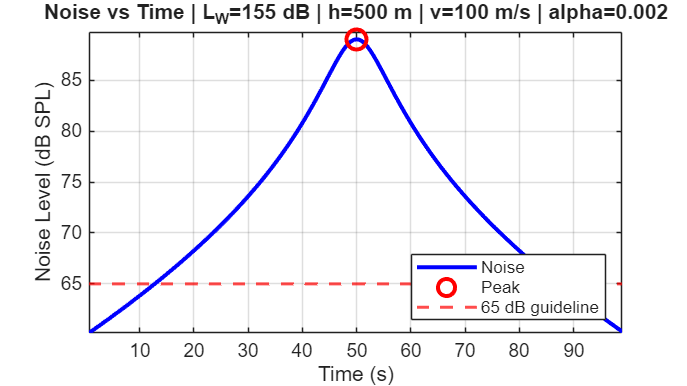


%% noise vs time

figure('Name','Noise vs. Time','NumberTitle','off','Position',[100 100 800 450]);

plot(t_hist, dB_hist, 'b-', 'LineWidth', 2);
hold on;

plot(t_peak, peak_dB, 'ro', 'MarkerSize', 10, 'LineWidth', 2);

yline(65, 'r--', 'LineWidth', 1.5);

xlabel('Time (s)');
ylabel('Noise Level (dB SPL)');

title(sprintf('Noise vs Time | L_W=%d dB | h=%d m | v=%d m/s | alpha=%.3f', ...
    L_W, h, v, alpha));

legend('Noise','Peak','65 dB guideline','Location','southeast');
grid on;

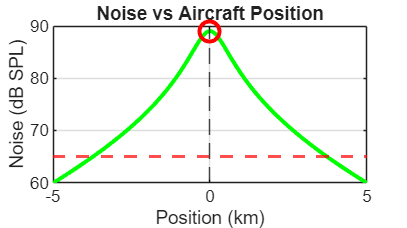


%% noise vs distance

figure('Name','Noise vs. Distance','NumberTitle','off','Position',[100 600 800 450]);

plot(x_hist/1000, dB_hist, 'g-', 'LineWidth', 2);
hold on;

xline(0, 'k--');
yline(65, 'r--', 'LineWidth', 1.5);

plot(x_peak/1000, peak_dB, 'ro', 'MarkerSize', 10, 'LineWidth', 2);

xlabel('Position (km)');
ylabel('Noise (dB SPL)');
title('Noise vs Aircraft Position');
grid on;

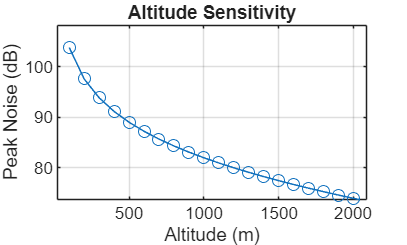


%% altitude sensitivity

alt_range = 100:100:3000;
peak_vs_alt = zeros(size(alt_range));

for k = 1:length(alt_range)

    h_k = alt_range(k);
    x_k = -5000;
    dB_max = 0;

    while x_k <= x_end
        r_k = sqrt(x_k^2 + h_k^2);
        dB_k = L_W - 20*log10(r_k) - 11 - alpha*r_k;
        dB_max = max(dB_max, dB_k);
        x_k = x_k + v*dt;
    end

    peak_vs_alt(k) = dB_max;

end

figure;
plot(alt_range, peak_vs_alt, 'o-');
hold on;
yline(65,'k--');

xlabel('Altitude (m)');
ylabel('Peak Noise (dB)');
title('Altitude Sensitivity');
grid on;


%% summary

fprintf('====================================================\n');

fprintf(' Airport Noise Simulation\n');

 Airport Noise Simulation


fprintf(' L_W=%d dB | h=%d m | v=%d m/s | alpha=%.3f\n', L_W, h, v, alpha);

 L_W=155 dB | h=500 m | v=100 m/s | alpha=0.002


fprintf('====================================================\n');


step = max(1, floor(length(t_hist)/15));

for i = 1:step:length(t_hist)
    fprintf('%6.1f %8.0f %8.1f\n', t_hist(i), x_hist(i), dB_hist(i));
end

   0.0    -5000     59.9
   6.5    -4350     62.4
  13.0    -3700     65.1
  19.5    -3050     68.0
  26.0    -2400     71.3
  32.5    -1750     75.2
  39.0    -1100     79.9
  45.5     -450     86.1
  52.0      200     88.3
  58.5      850     82.1
  65.0     1500     76.9
  71.5     2150     72.7
  78.0     2800     69.2
  84.5     3450     66.2
  91.0     4100     63.4
  97.5     4750     60.9



fprintf('Peak: %.1f dB at t=%.1f s\n', peak_dB, t_peak);

Peak: 89.0 dB at t=50.0 s



r_peak = h;
dB_analytic = L_W - 20*log10(r_peak) - 11 - alpha*r_peak;

fprintf('Analytical peak: %.2f dB\n', dB_analytic);

Analytical peak: 89.02 dB


fprintf('Difference: %.2f dB\n', abs(dB_analytic - peak_dB));

Difference: 0.00 dB
